# Problema 6 - Tp7

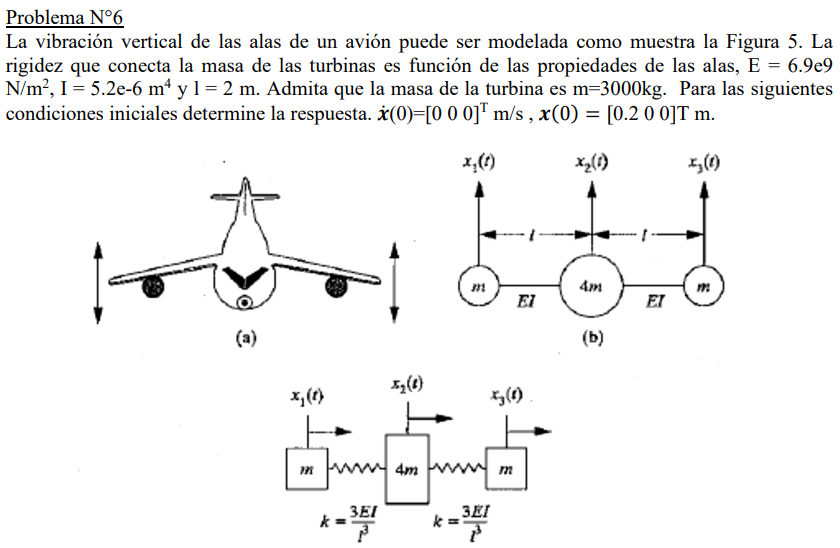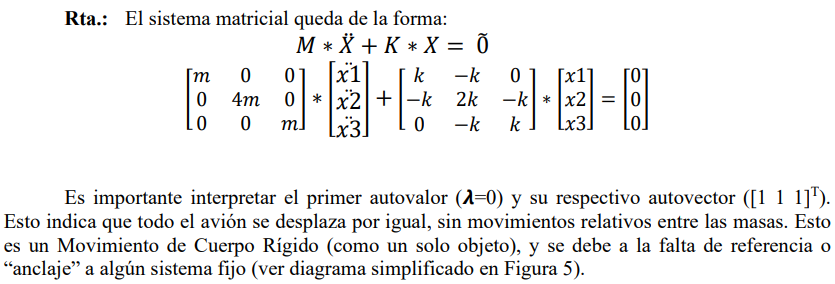

## Cálculo de matriz M y K

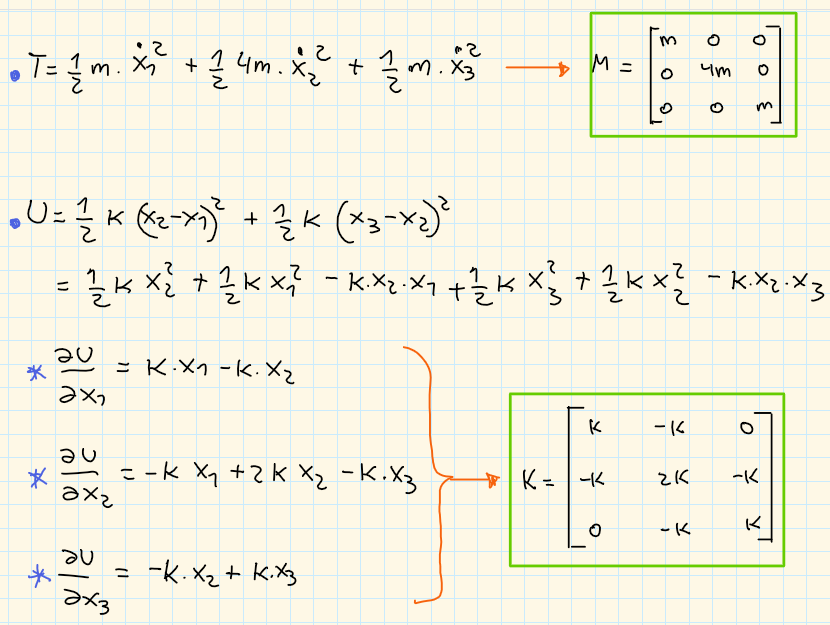

## Solución

clc; clear;

%% ---------------- DATOS DEL SISTEMA -----------------------

%Masas (seleccionadas de forma arbitraria, pero teniendo en cuenta que)
m=3000;
m1=m;
m2=4*m;
m3=m;
M = diag([m1,m2,m3]);

%Rigidez
E=6.9*10^9;
I=5.2*10^(-6);
l=2;
k=3*E*I/l;

K = [k    -k    0;
    -k    2*k  -k;
     0    -k    k];

%Condiciones iniciales
x0 = [0.2; 0; 0]; %Desplazamientos iniciales
dx0 = [0; 0; 0] ; %Velocidades iniciales

%Tiempo para graficar
tf=10;
dt=0.01;
t=0:dt:tf;

%Relacion de amortiguamiento crítico
zitta = [0; 0; 0];

%% ------------------ AUTOVECTORES Y AUTOVALORES ------------------

[V,lambda] = eig(K,M);
w = diag(sqrt(lambda))

w =     0.0000
    4.2356
    5.1875


V_norm = V ./ V(1,:)

V_norm =     1.0000    1.0000    1.0000
    1.0000    0.0000   -0.5000
    1.0000   -1.0000    1.0000




%% ----------------- MATRICES MODALES -----------------------------

Mmodal = round(V' * M * V);
Kmodal = round(V' * K * V);
Cmodal = 2*zitta.*w.*eye(size(M));

%zitta = diag(Cmodal./(2*w));         %Puedo calcular los zittas para cada modo de vibración usando esta fórmula (ChatGPT)

Y0 = V' * M * x0;                   %desplazamiento inicial en coordenadas modales
dY0 = V' * M * dx0;                 %velocidad inicial en coordenadas modales

%La ecuación diferencial a resolver es la siguiente:
%Mmodal*y''(t) + Cmodal*y'(t) + Kmodal*y(t) = 0

%%--------------RESOLUCIÓN EDO------------------------------------

%Ahora tengo un sistema del tipo Mmodal*y''+Kmodal*y=0 Como Mmodal y Kmodal
%son diagonales, es como si tuviera varias ecuaciones diferenciales
%simples.

%Para sistemas amortiguados, la solución es::
%

wd = w.*sqrt(1-zitta.^2); %frecuencia natural del sistema amortiguado
e=exp(1);

Y = zeros(length(w),length(t));

for i = 1:length(w)
    
    %Primer término
    Y(i,:) = e.^(-zitta(i)*w(i)*t).*( cos(wd(i)*t) + zitta(i)/sqrt(1-zitta(i)^2) * sin(wd(i)*t)).*Y0(i);
    
    %Segundo término
    Y(i,:) = Y(i,:)+ dY0(i) * (1/wd(i)*e.^(-zitta(i)*w(i)*t).*sin(wd(i)*t));
    
    %El tercer término no afecta porque es sólo si hay cargas externas
    %aplicadas
end

%Ahora paso de coordenadas modales a geométricas
X = V * Y;


%Analizo amplitud de x1
X1max=max(X(1,:))

X1max = 0.2000



%Analizo amplitud de x2
X2max=max(X(2,:))

X2max = 0.0667


%Analizo amplitud de x3
X3max=max(X(3,:))

X3max = 0.1990

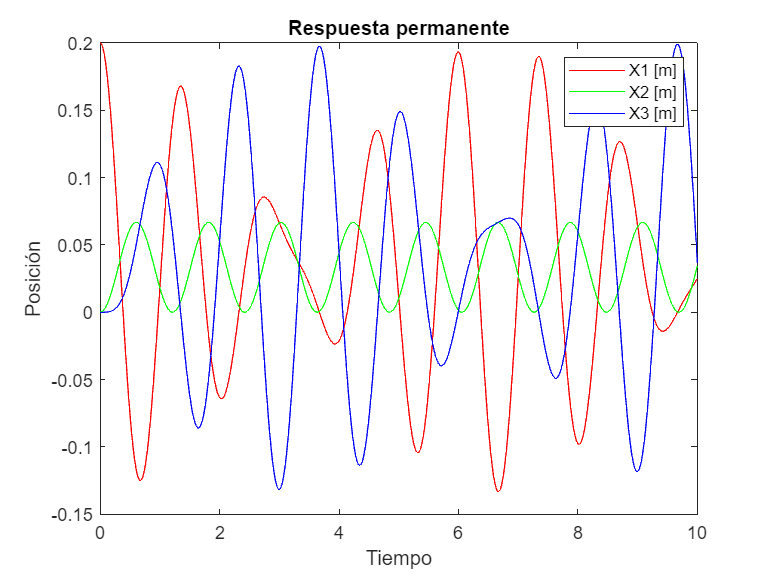



% Graficar las posiciones de las partículas
figure
plot(t, X(1,:), 'r', t, X(2,:), 'g', t, X(3,:), 'b');
xlabel('Tiempo');
ylabel('Posición');
legend('X1 [m]', 'X2 [m]', 'X3 [m]');
title('Respuesta permanente');